clear 
clc

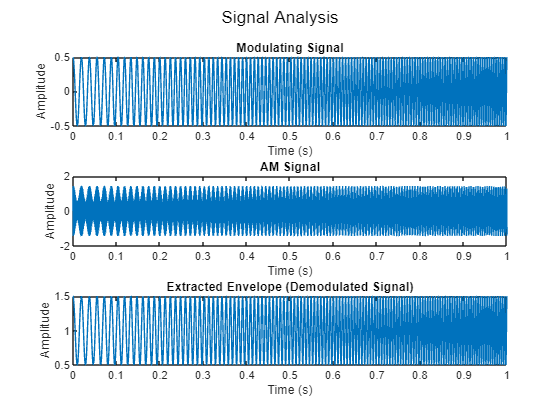

%Task2.1
% Parameters
fs = 1e4; % Sampling rate
t = 0:1/fs:1-1/fs; % Time vector

% Generate signals
y_mod = 0.5 * chirp(t, 50, t(end), 200); % Chirp signal
y_carr = sin(2 * pi * t * 1e3); % Carrier signal
y = y_mod .* y_carr + y_carr; % Modulated signal

% Calculate the envelope using the Hilbert transform
y_hilbert = hilbert(y); % Compute the analytic signal
envelope = abs(y_hilbert); % Envelope of the signal

% Low-pass filter design
cutoff_frequency = 1100;  % Cutoff frequency for low-pass filter (just above the modulating frequency)
order = 5;              % Filter order
[b, a] = butter(order, cutoff_frequency / (fs / 2), 'low');

% Apply low-pass filter to the envelope
filtered_envelope = filtfilt(b, a, envelope);

% Plot the signals
figure;

subplot(3, 1, 1);
plot(t, y_mod);
title('Modulating Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3, 1, 2);
plot(t, y);
title('AM Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3, 1, 3);
plot(t, filtered_envelope);
title('Extracted Envelope (Demodulated Signal)');
xlabel('Time (s)');
ylabel('Amplitude');

% Adjust the layout
sgtitle('Signal Analysis');

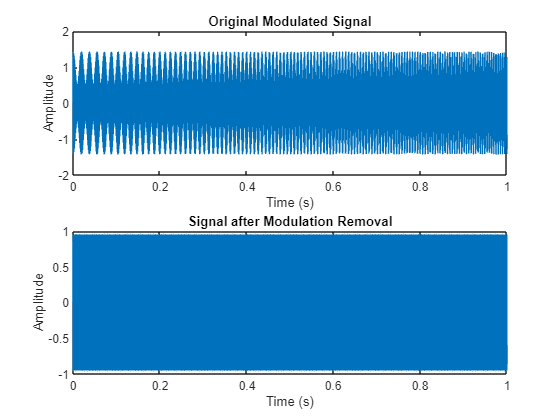

% Remove modulation
y_no_mod = y ./ envelope; % Normalize by envelope to remove modulation

% Frequency-Amplitude plots
figure;
subplot(2, 1, 1);
plot(t, y);
title('Original Modulated Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2, 1, 2);
plot(t, y_no_mod);
title('Signal after Modulation Removal');
xlabel('Time (s)');
ylabel('Amplitude');

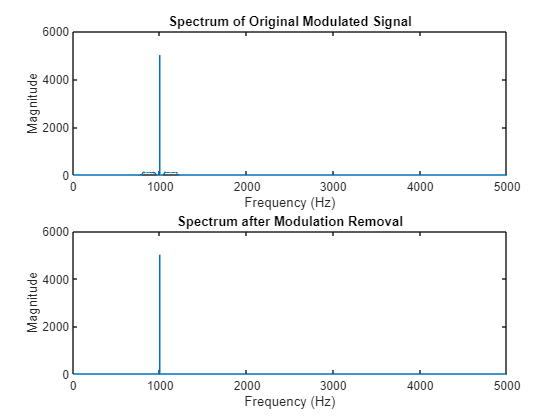


% Spectral analysis
Y = fft(y);
Y_no_mod = fft(y_no_mod);
f = (0:length(Y)-1) * fs / length(Y); % Frequency vector

figure;
subplot(2, 1, 1);
plot(f(1:fs/2), abs(Y(1:fs/2)));
title('Spectrum of Original Modulated Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');


subplot(2, 1, 2);
plot(f(1:fs/2), abs(Y_no_mod(1:fs/2)));
title('Spectrum after Modulation Removal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
ylim([0 6000])

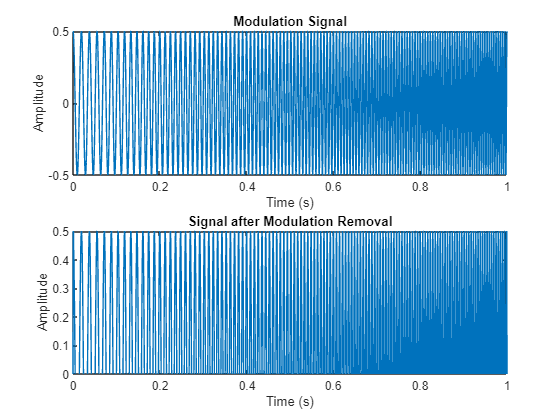

%Task2.2
y_demod = y .* y_carr;
fpass = 400;
y_filt = lowpass( y_demod,fpass,fs );
y_filt = y_filt - mean( y_filt );
y_filt = y_filt * 2;

% Frequency-Amplitude plots
figure;
subplot(2, 1, 1);
plot(t, y_mod);
title('Modulation Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2, 1, 2);
plot(t, y_filt);
title('Signal after Modulation Removal');
xlabel('Time (s)');
ylabel('Amplitude');
ylim([0 0.5])

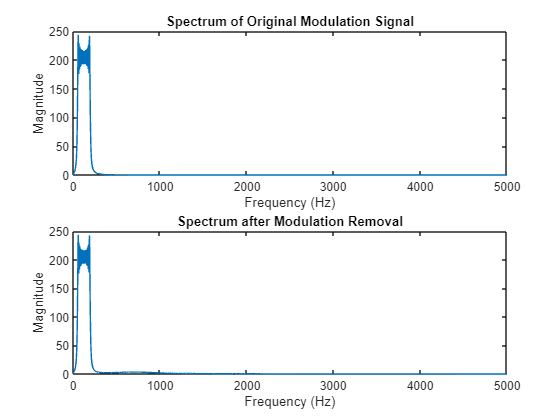


% Spectral analysis
Y_filt = fft(y_filt);
Y_mod = fft(y_mod);
f = (0:length(Y)-1) * fs / length(Y); % Frequency vector

figure;
subplot(2, 1, 1);
plot(f(1:fs/2), abs(Y_mod(1:fs/2)));
title('Spectrum of Original Modulation Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');


subplot(2, 1, 2);
plot(f(1:fs/2), abs(Y_filt(1:fs/2)));
title('Spectrum after Modulation Removal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
ylim([0 250])

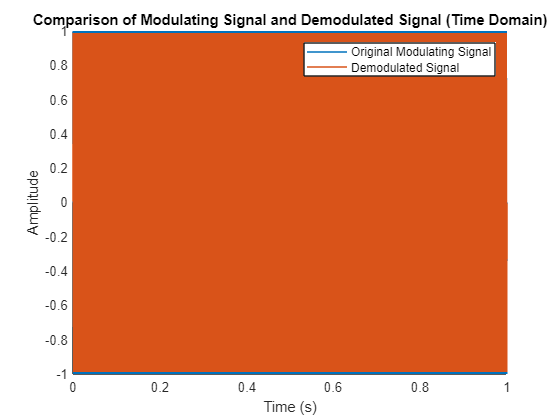

%task3
fs = 2e5;
dt = 1/fs;
fc = 1e4;
t = 0:1/fs:1;
y_mod = sin(2*pi*t*500);
y_carr = sin(2*pi*t*fc);
y = sin(2*pi*t* fc+y_mod );
y_diff = diff(y)/dt;

y_env = hilbert(y_diff);
y_env = abs(y_env);

y_env = y_env - mean( y_env );
y_dem = inteFD (y_env,1/fs);

Y_mod = fft(y_mod);
Y_dem = fft(y_dem);

f_mod = (0:length(Y_mod)-1) * fs / length(Y_mod);
f_dem = (0:length(Y_dem)-1) * fs / length(Y_dem);

figure()
plot(t, y_mod);
hold on;
plot(t(1:end-1), y_dem);
hold off;
title('Comparison of Modulating Signal and Demodulated Signal (Time Domain)');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Original Modulating Signal', 'Demodulated Signal');

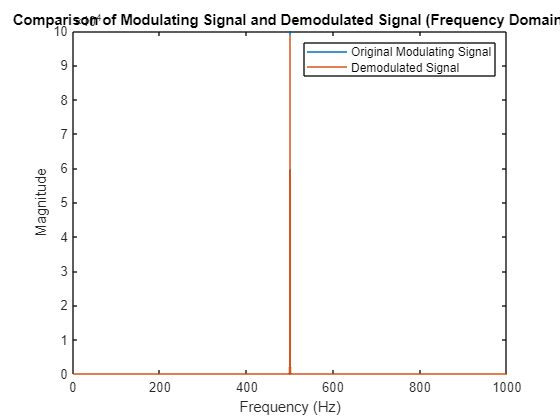

figure()
plot(f_mod(1:fs/2), abs(Y_mod(1:fs/2)));
hold on;
plot(f_dem(1:fs/2), abs(Y_dem(1:fs/2)));
hold off;
xlim([0 1000])
title('Comparison of Modulating Signal and Demodulated Signal (Frequency Domain)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend('Original Modulating Signal', 'Demodulated Signal');

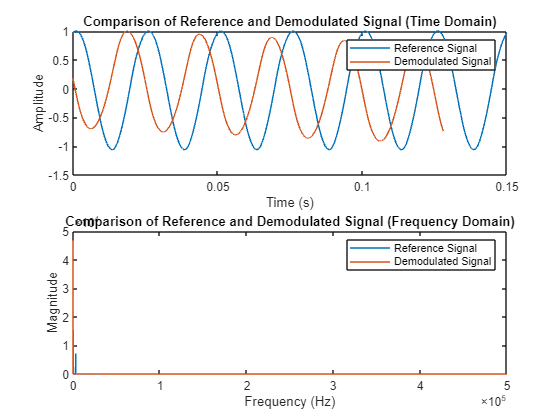

%task4
% Load the data
d0 = load("40Hz.mat");
d1 = load("40Hz_ref.mat");

% Extract the necessary data
t_meas = d1.t_meas;
y_meas = d1.y_meas;
fs = 1e6;
t = 0:1/fs:(length(d0.A)-1)/fs; % Adjusting time vector to the length of the signal
y = d0.A;

% Bandpass filter around the 100 kHz carrier frequency
y = bandpass(y, [0.8e5, 1.2e5], fs);

% Remove amplitude modulations
y_env = abs(hilbert(y));
y_demod = y ./ y_env;

% Frequency demodulation
dt = 1/fs;
y_diff = diff(y_demod)/dt; %!!!
y_env = abs(hilbert(y_diff));
y_env = y_env - mean(y_env);
y_dem = y_env(100:end-100);
y_dem = lowpass(y_dem, 1000, fs); %!!!
y_dem = y_dem/2;
y_dem = inteFD(y_dem, 1/fs);
% Ensure y_dem length matches y_meas
y_dem = y_dem(1:length(y_meas));
y_dem = detrend(y_dem);
tmp = (0:length(y_dem)-1)/fs;
% Display waveforms and spectra
figure;

% Time domain plot
subplot(2, 1, 1);
plot(t_meas, y_meas./max(y_meas));
hold on;
plot(tmp, y_dem./max(y_dem));
hold off;
title('Comparison of Reference and Demodulated Signal (Time Domain)');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Reference Signal', 'Demodulated Signal');
xlim([0 0.15])
% Frequency domain plot
Y_meas = fft(y_meas);
Y_dem = fft(y_dem);

f = (0:length(Y_meas)-1) * fs / length(Y_meas); % Frequency vector

subplot(2, 1, 2);
plot(f(1:floor(length(f)/2)), abs(Y_meas(1:floor(length(f)/2))));
hold on;
plot(f(1:floor(length(f)/2)), abs(Y_dem(1:floor(length(f)/2))));
hold off;
title('Comparison of Reference and Demodulated Signal (Frequency Domain)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

legend('Reference Signal', 'Demodulated Signal');